Consider a disc of radius $\alpha \;$ tolling down a ramp whose height at position $x$ is $f\left(x\right)$. Say that the center of the ball, which is also the center of mass is at position $\left(x\left(t\right),y\left(t\right)\right)$ and that the disc contacts the ramp at position $\left(\textrm{cpx}\left(t\right),\textrm{cpy}\left(t\right)\right)$ .

clear all
syms x(t) y(t) theta1(t) theta2(t) cpx(t) cpy(t) f(z) F1(t) F2(t) s 
%Set paramters. 
m=1; alpha=1; g=[0;9.81];

%ramp is just inclined with slope 3. Best to use z for the variable of f.
%If you use x it will get confused with the name of the function x(t). 
phi=pi/6;
f(z)=1/8*z^2;

%MOI of disc about COM. 
IG=1/2*m*alpha^2;

%Position of COM.
rG=[x(t);y(t)];

%Contact forces. 
F=[F1(t);F2(t)];

%Contact point
cp=[cpx(t);cpy(t)];

%COLM
eq1=m*diff(rG,2)==F-m*g

$$eq1 = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=F_{1}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=F_{2}\left(t\right)-\frac{981}{100} \end{array}\right)$$

%COAM
MFG=cross([cp-rG;0],[F;0]);
eq2=IG*diff(theta1+theta2,2)==MFG(3)

$$eq2(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{2}+\frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{2}=F_{2}\left(t\right)\,\left(\mathrm{cpx}\left(t\right)-x\left(t\right)\right)-F_{1}\left(t\right)\,\left(\mathrm{cpy}\left(t\right)-y\left(t\right)\right)$$

Ok, for the constraints.  Certainly the center of the ball must be $\alpha \;$ from the contact point.  I think it is true that in order for the ball to be nice an tangent to the curve, the center of the ball must be $\alpha \;$ units from the contact point in the orthogonal from the ramp direction.  So like this: 

%The tangnential direction to the wire is
T=[1;diff(f)]/sqrt(1+diff(f)^2)

$$T(z) = \left(\begin{array}{c} \frac{1}{\sqrt{\frac{z^{2}}{16}+1}}\\ \frac{z}{4\,\sqrt{\frac{z^{2}}{16}+1}} \end{array}\right)$$

%The normal direction to the wire is
N=[-diff(f);1]/sqrt(1+diff(f)^2)

$$N(z) = \left(\begin{array}{c} -\frac{z}{4\,\sqrt{\frac{z^{2}}{16}+1}}\\ \frac{1}{\sqrt{\frac{z^{2}}{16}+1}} \end{array}\right)$$

%rG must be alpha from cp in the normal direction from (cpx,xpy).
eq4=rG==[cpx;cpy]+alpha*N(cpx)

$$eq4(t) = \left(\begin{array}{c} x\left(t\right)=\mathrm{cpx}\left(t\right)-\frac{\mathrm{cpx}\left(t\right)}{4\,\sqrt{\frac{{\mathrm{cpx}\left(t\right)}^{2}}{16}+1}}\\ y\left(t\right)=\mathrm{cpy}\left(t\right)+\frac{1}{\sqrt{\frac{{\mathrm{cpx}\left(t\right)}^{2}}{16}+1}} \end{array}\right)$$

%cp must be on the wire. 
eq5=cpy==f(cpx)

$$eq5(t) = \mathrm{cpy}\left(t\right)=\frac{{\mathrm{cpx}\left(t\right)}^{2}}{8}$$

Ok, we now have 7 unkown functions.  $x\left(t\right)$, $y\left(t\right)$, $\textrm{cpx}\left(t\right)$, $\textrm{cpy}\left(t\right)$, $\textrm{theta}\left(t\right)$, $\textrm{F1}\left(t\right)$, $\textrm{F2}\left(t\right)$.  We have 3 equations of motion, and three constraints just keeping the ball in correct contact with the ramp.  So, we only get one more equation, that rules out the normal vector formulation of roll without slip.  However, the way we've set things up, the ball will roll in the correct direction.  That's because we require


$$\textrm{rG}\left(t\right)=\textrm{cp}\left(t\right)+\alpha \;N\left(t\right)$$


so that 


$${\textrm{rG}}^{\prime } \left(t\right)={\textrm{cp}}^{\prime } \left(t\right)+\alpha \;T\left(t\right)\;$$


Now $\textrm{cp}\left(t\right)$ is required to move along the ramp, so 

${\textrm{cp}}^{\prime } \left(t\right)=\beta \;T\left(t\right)$ for some constant $\beta \;$.  Thus


$${\textrm{rG}}^{\prime } \left(t\right)=\left(\alpha +\beta \;\right)T\left(t\right)$$


The point is that these constraints get the ball rolling in the correct direction, now we just need the right speed.  

One potential concern I have is that we haven't really decided what exactly it is that $\theta \;$ means yet.  

Anyway, I think what we want to say is that after the ball has rotated through $\theta \;$radians, it must be at a position on the ramp that is $\alpha \;\theta \;$units of arc-length down the ramp. This can be done.  The amount of arclength on the ramp between $x=a$ and $x=b$ can be calculated by 


$$\int_a^b \sqrt{1+f^{\prime } {\left(s\right)}^2 }\;\textrm{ds}\ldotp$$


At time $t$ the ball is at position (on the ramp) $\left(\textrm{cpx}\left(t\right),\textrm{cpy}\left(t\right)\right)$. Assuming that $\theta \left(0\right)=0$,  what is want is at all times $t$, 


$$\alpha \;\theta \left(t\right)=\int_{\textrm{cpx}\left(0\right)}^{\textrm{cpx}\left(t\right)} \sqrt{1+f^{\prime } {\left(s\right)}^2 }\textrm{ds}\;$$


For the sake of argument let's promise to start at $\textrm{cpx}\left(0\right)=1$. Then we get 


$$\alpha \;\theta \left(t\right)=\int_1^{\textrm{cpx}\left(t\right)} \sqrt{1+f^{\prime } {\left(s\right)}^2 }\;\textrm{ds}\;\;$$


Now, this is too many constraints.  Position constraints really turn into two constraintes, because you differentiate them twice.  

%eq6=sqrt(diff(cpx)^2+diff(cpy)^2)==-sqrt(alpha^2*diff(theta)^2)
df=diff(f);
eq6=alpha*diff(theta2,t)==-sqrt(1+(df(cpx(t))^2))*diff(cpx(t));

%relate theta1 back to the curve. 

%This gives the angle the normal vector makes with vertical at position x. 
ang=atan(diff(f))

$$ang(z) = \mathrm{atan}\left(\frac{z}{4}\right)$$


eq7=theta1==ang(cpx(t))

$$eq7(t) = \theta_{1}\left(t\right)=\mathrm{atan}\left(\frac{\mathrm{cpx}\left(t\right)}{4}\right)$$

eq8=diff(eq7)

$$eq8(t) = \frac{\partial }{\partial t}\theta_{1}\left(t\right)=\frac{\frac{\partial }{\partial t}\mathrm{cpx}\left(t\right)}{4\,\left(\frac{{\mathrm{cpx}\left(t\right)}^{2}}{16}+1\right)}$$



%Equations of motion
DEs=[eq1;eq2];

%I am unsure how to make the number of euqations vs constraints work out. 

positionConstraint=[eq4;eq5];

%Roll without slip condition. 
velocityConstraint=[eq6;eq8];


The unknown functions (just the base functions, not derivatives) are: F1(t),F2(t),cpx(t),cpy(t),theta1(t),theta2(t),x(t),y(t)


Multiple feasible initial conditions found:
Dcpxt: 0.000000    Dcpyt: 0.000000    Dtheta1t: 0.000000    Dxt: 0.000000    Dyt: 0.000000    cpx: -0.057357    cpy: -1.897829    y: 2.117276    
Dcpxt: 0.000000    Dcpyt: 0.000000    Dtheta1t: 0.000000    Dxt: 0.000000    Dyt: 0.000000    cpx: -0.057357    cpy: -1.897829    y: 2.117276    
Dcpxt: 0.000000    Dcpyt: 0.000000    Dtheta1t: 0.000000    Dxt: 0.000000    Dyt: 0.000000    cpx: 0.803143    cpy: 0.080630    y: 1.061062    
Dcpxt: 0.000000    Dcpyt: 0.000000    Dtheta1t: 0.000000    Dxt: 0.000000    Dyt: 0.000000    cpx: 1.311571    cpy: 0.215027    y: 1.165250    

Selecting IC:
Dcpxt:0.000000    Dcpyt:0.000000    Dtheta1t:0.000000    Dxt:0.000000    Dyt:0.000000    cpx:-0.057357    cpy:-1.897829    y:2.117276    
Because it is first.  Use a hint if you want to select a different initial condition.

Initial Conditions:
Y0/YP0:
F1: 53.919249 F1t:0.000000
F2: 101.814162 F2t:0.000000
cpx: -0.057357 cpxt:0.000000
cpy: -1.897829 cpyt:0.00

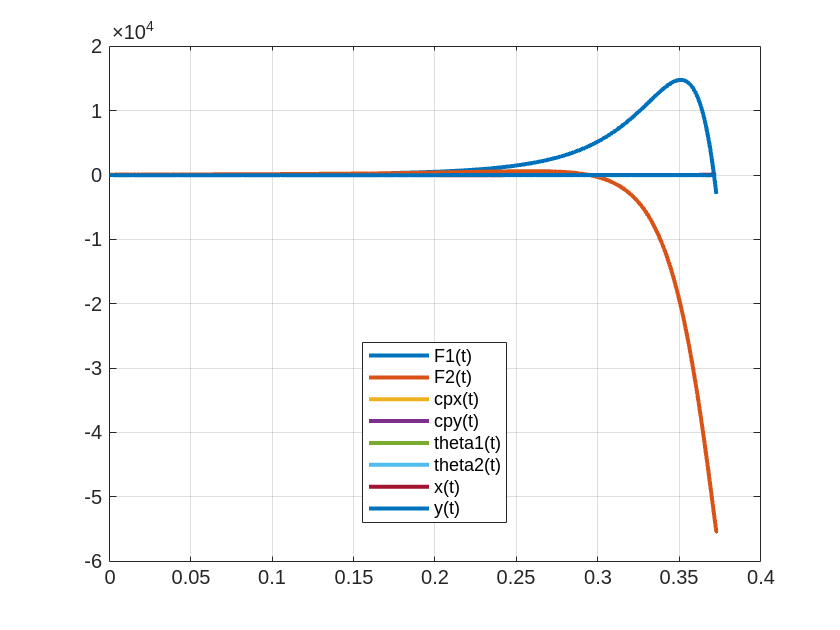

soln = struct with fields:
           t: [229×1 double]
          F1: [229×1 double]
          F2: [229×1 double]
         cpx: [229×1 double]
         cpy: [229×1 double]
      theta1: [229×1 double]
      theta2: [229×1 double]
           x: [229×1 double]
           y: [229×1 double]
       Dcpxt: [229×1 double]
       Dcpyt: [229×1 double]
    Dtheta1t: [229×1 double]
    Dtheta2t: [229×1 double]
         Dxt: [229×1 double]
         Dyt: [229×1 double]


%Solve! Keep promise that cpx(0)=1. 

soln=mechanicsAsDAE(DEs,positionConstraint,velocityConstraint,[0,3],[theta1==ang(1), theta2==0, x==1,diff(theta2)==0])

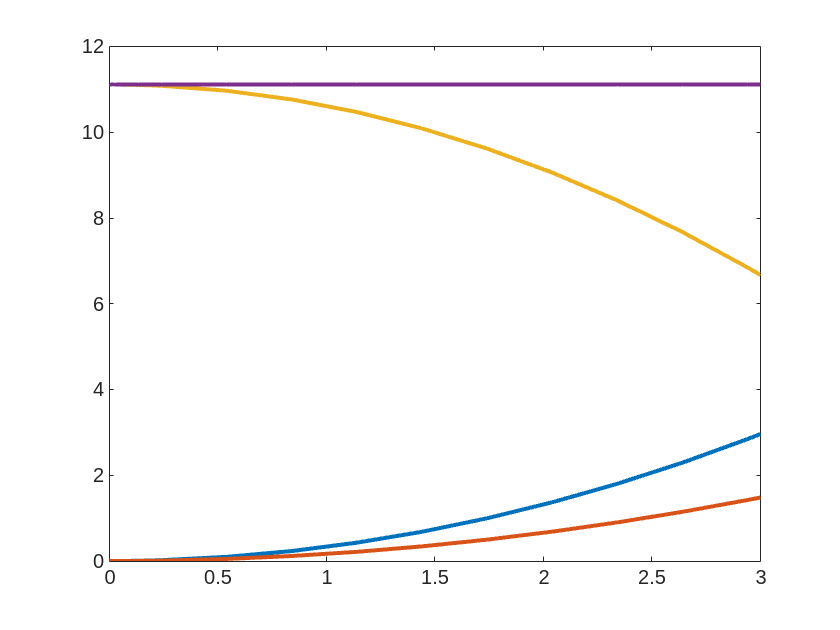

KLE=1/2*m*(soln.Dxt.^2+soln.Dyt.^2);
KRE=1/2*IG*(soln.Dtheta1t+soln.Dtheta2t).^2;
PE=m*soln.y*g(2);

plot(soln.t,KLE,soln.t,KRE,soln.t,PE,soln.t,KLE+KRE+PE,'LineWidth',2);

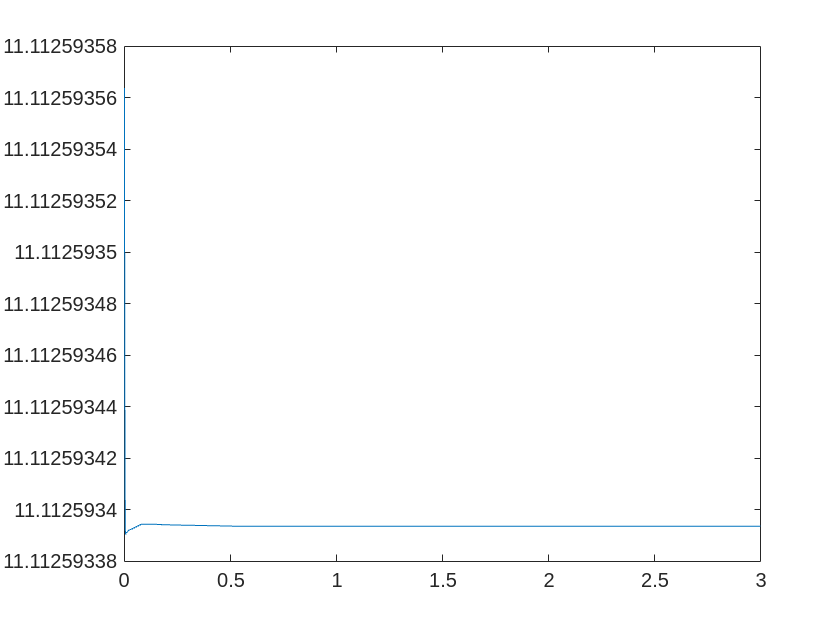

plot(soln.t,KLE+KRE+PE)


[govDEs,PPs]=analyzeSystem(DEs,positionConstraint,velocityConstraint,[theta,diff(theta),x]);

The unknown functions are:
F1(force)
F2(force)
cpx
cpy
theta
x
y

Expected Number of State Variables:3


soln=timeStepODESystem(govDEs,[0,10],[theta==0,diff(theta)==1,x==0],PPs,0);
plot(soln.t,soln.x,soln.t,soln.y,soln.t,soln.theta,'LineWidth',2); legend({"x","y","theta"}); grid on;
